%% Constants
mu   = 398600.4418;          % [km^3/s^2]
Re   = 6378.1363;            % [km]
J2   = 1.08262668e-3;        % [-]
we   = 7.2921159e-5;         % [rad/s] Earth rotation (sidereal)

%% Assignment assumptions
Omega = deg2rad(0);
omega = deg2rad(0);
nu0   = deg2rad(0);       % true anomaly at t0

Defining Constants and Values for the functions

% Example initial elements (radians). Assignment says ω=Ω=ν=0°
a = 7000;                         % km  (pick any bound, elliptical orbit)
e = 0.01;
i = deg2rad(51.6);                % can be anything for 1a

t0 = 0;                           % s
n  = sqrt(mu/a^3);
T  = 2*pi/n;                      % one period
tf = 2*T;                         % propagate 2 orbits just to test
dt = 60;                          % reasonable step for 1a


Choose dt according to weakest chain in the OD

1b) SSO inclination (hp=550 km, e=0.01), propagate 30 revs

Re  = 6378.1363;                % km
J2  = 1.08262668e-3;            % -
year_sec = 365.2422*86400;      % s
Omega_dot_target = 2*pi/year_sec; % rad/s (sun-synchronous)

% Given orbit parameters
hp = 550;                       % km (perigee height)
e  = 0.01;
rp = Re + hp;                   % km
a  = rp/(1 - e);                % km
p  = a*(1 - e^2);
n  = sqrt(mu/a^3);              % rad/s

% SSO inclination from J2 nodal regression: dΩ/dt = -(3/2) J2 n (Re/p)^2 cos(i)
cosi = -Omega_dot_target / (1.5*J2*n*(Re/p)^2);
i    = acos(max(-1,min(1,cosi)));  % radians (clamped)

% Assignment angles
Omega = 0; omega = 0; nu0 = 0;

% Propagate 30 orbits
T  = 2*pi/n; 
orbits = 30;
t0 = 0; tf = orbits*T; 
dt = 60;

Run 1b)

[t_vec, r_eci, v_eci] = Orbit.propagateKeplerNewton(a,e,i,Omega,omega,nu0,mu,t0,tf,dt);

Helper Function for Task 1: Propagates unperturbed Keplerian motion using Newton's method for Kepler's eq. then returns time vector and ECI (ICRF) r,v arrays

Now Plotting the Orbit. First for the plot itself a few variables like earth itself and so on...

Re = 6378.1363;            % km
we = 7.2921159e-5;         % rad/s (Earth rotation rate)
theta_g0 = 0;              % GMST at t0 (assume 0 for assignment)
t0 = t_vec(1);

Now for the plot itself:

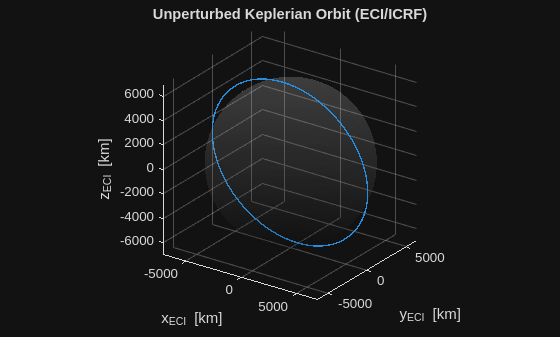

figure('Name','3D Orbit (ECI)');
plot3(r_eci(:,1), r_eci(:,2), r_eci(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
% Draw a translucent Earth
[fX,fY,fZ] = sphere(80);
surf(Re*fX, Re*fY, Re*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none'); colormap gray;
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Unperturbed Keplerian Orbit (ECI/ICRF)');
view(35,25);

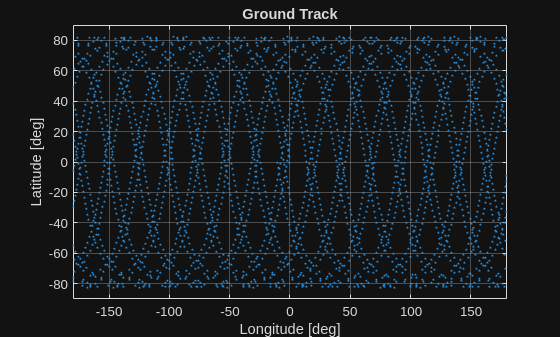


% -------- Ground Track --------
N  = size(r_eci,1);
lat_deg = zeros(N,1);
lon_deg = zeros(N,1);

for k = 1:N
    theta = theta_g0 + we*(t_vec(k) - t0);   % Earth rotation since t0
    % ECI -> ECEF: rotate about z by -theta
    R3m = [ cos(theta)  sin(theta) 0;
        -sin(theta)  cos(theta) 0;
        0           0     1];
    r_ecef = R3m * r_eci(k,:).';
    
    x = r_ecef(1); y = r_ecef(2); z = r_ecef(3);
    r_norm = hypot(hypot(x,y), z);
    
    lat = asin(z / r_norm);
    lon = atan2(y, x);
    
    lat_deg(k) = rad2deg(lat);
    lon_deg(k) = rad2deg(lon);
end

% Wrap longitudes to [-180,180]
lon_deg = mod(lon_deg + 180, 360) - 180;

figure('Name','Ground Track');
plot(lon_deg, lat_deg, '.', 'MarkerSize', 4); grid on;
xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]');
title('Ground Track');

TASK 2)

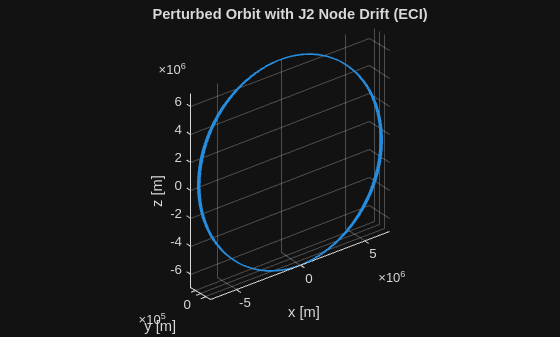

mu = 3.986004418e14;      % m^3/s^2
Re = 6378137.0;           % m
J2 = 1.08262668e-3;       % -
wE = 7.2921150e-5;        % rad/s
omega = 0; Omega0 = 0; nu0 = 0;  % rad
t0 = 0;                          % s
OmegaDot_want = -2*pi/(365.2422*86400);

%% Orbit: SSO with hp=550 km, e=0.01
hp = 550e3; e = 0.01;
a  = (Re + hp)/(1 - e);

% target sun-sync RAAN drift: -360 deg per sidereal year
i = Orbit.ssoInclination(a, e, OmegaDot_want, mu, J2, Re);  % rad/s

% time span: 30 revolutions
n  = sqrt(mu/a^3);
T  = 2*pi/n;
tf = t0 + 30*T;
dt = 10;

%% Propagate with J2 node drift (ICRF/ECI outputs)
[t, R_eci, V_eci, Omegadot] = Orbit.propagateKeplerJ2Node( ...
    a,e,i,Omega0,omega,nu0,mu,J2,Re,t0,tf,dt);

% save Cartesian positions as required
R_icrf = R_eci;  % inertial == ICRF here

%% 3D orbit plot
figure; plot3(R_eci(:,1),R_eci(:,2),R_eci(:,3),'LineWidth',1);
grid on; axis equal;
xlabel('x [m]'); ylabel('y [m]'); zlabel('z [m]');
title('Perturbed Orbit with J2 Node Drift (ECI)');

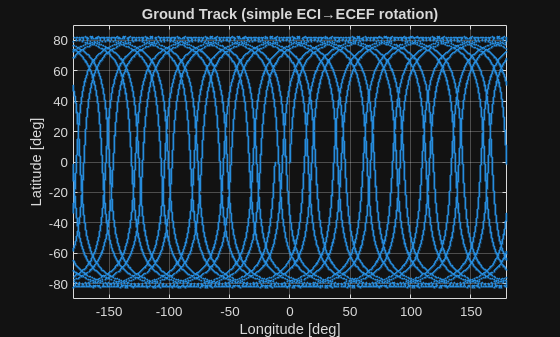

thetaG0 = 0;   % choose reference GST
N = size(R_eci,1);
lat = zeros(N,1); lon = zeros(N,1);

for k = 1:N
    theta = thetaG0 + wE*(t(k) - t0);
    R3 = [ cos(theta)  sin(theta) 0;
          -sin(theta)  cos(theta) 0;
           0           0          1 ];
    r_ecef = R3 * R_eci(k,:).';
    x=r_ecef(1); y=r_ecef(2); z=r_ecef(3);
    lon(k) = atan2(y,x);
    lat(k) = atan2(z, sqrt(x^2 + y^2));
end

lon_deg = rad2deg(mod(lon+pi,2*pi)-pi);
lat_deg = rad2deg(lat);

figure; plot(lon_deg, lat_deg, '.', 'MarkerSize', 4);
grid on; xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]');
title('Ground Track (simple ECI→ECEF rotation)');

Task 3)

%% Assignment angles & epoch
omega = 0; Omega0 = 0; nu0 = 0;  % rad
t0 = 0;                          % s

%% Orbit: SSO with hp=550 km, e=0.01
hp = 550e3; e = 0.01;
a  = (Re + hp)/(1 - e);

n  = sqrt(mu/a^3);
p  = a*(1 - e^2);
cosi = -OmegaDot_want / (1.5 * J2 * (Re^2/p^2) * n);
cosi = max(-1,min(1,cosi));
i = acos(cosi);

%% Initial state (r0,v0) from Keplerian elements at nu0, omega, Omega0
p   = a*(1 - e^2);
r   = p/(1 + e*cos(nu0));
r_pqw = [ r*cos(nu0); r*sin(nu0); 0 ];
v_pqw = sqrt(mu/p) * [ -sin(nu0); e + cos(nu0); 0 ];

cO = cos(Omega0); sO = sin(Omega0);
ci = cos(i);      si = sin(i);
co = cos(omega);  so = sin(omega);
Q = [ cO*co - sO*so*ci,   -cO*so - sO*co*ci,   sO*si;
      sO*co + cO*so*ci,   -sO*so + cO*co*ci,  -cO*si;
      so*si,               co*si,             ci     ];

r0 = Q * r_pqw;
v0 = Q * v_pqw;

%% Time span: 30 revolutions
T  = 2*pi/n;                 % s
Nrev = 30;
tf = t0 + Nrev*T;
dt = 10;                     % s was sollen wir hier aussuchen?

% Unperturbed two-body
acc2B = @(t,r,v) (-mu) * r / (norm(r)^3);

% Two-body + J2 (z along Earth's spin axis)
accJ2 = @(t,r,v) ( ...
    (-mu) * r / (norm(r)^3) + ...
    (3/2)*J2*mu*Re^2/(norm(r)^5) * [ ...
        r(1)*(5*(r(3)^2)/norm(r)^2 - 1);
        r(2)*(5*(r(3)^2)/norm(r)^2 - 1);
        r(3)*(5*(r(3)^2)/norm(r)^2 - 3) ] );

Propagate unperturbaed EoM

[t, R_eci_unp, V_eci_unp] = Orbit.propagateRK4(t0, tf, dt, r0, v0, acc2B);

% Save Cartesian ICRF (ECI)
R_icrf_unp = R_eci_unp;

Propagate perurbed EoM with J2

%% Perturbed EoM propagation (RK4 + two-body + J2)
[tJ2, R_eci_J2, V_eci_J2] = Orbit.propagateRK4(t0, tf, dt, r0, v0, accJ2);

% Save Cartesian ICRF (ECI)
R_icrf_J2 = R_eci_J2;

Plot:

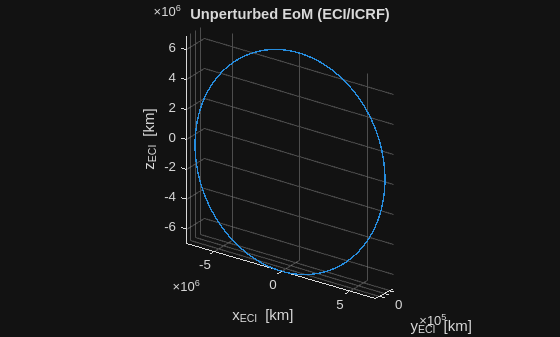

figure('Name','3D Orbit (ECI) - Unperturbed');
plot3(R_eci_unp(:,1), R_eci_unp(:,2), R_eci_unp(:,3), 'LineWidth', 1.0); hold on; grid on; axis equal;
[fX,fY,fZ] = sphere(80); surf((Re/1e3)*fX, (Re/1e3)*fY, (Re/1e3)*fZ, 'FaceAlpha', 0.1, 'EdgeColor', 'none');
xlabel('x_{ECI} [km]'); ylabel('y_{ECI} [km]'); zlabel('z_{ECI} [km]');
title('Unperturbed EoM (ECI/ICRF)'); view(35,25);

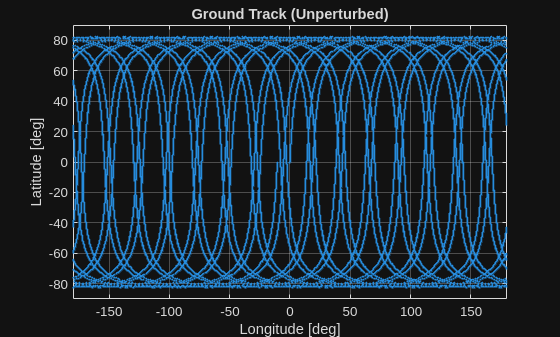

% -------- Ground Track, unperturbed --------
thetaG0 = 0;  % or your GMST(t0)
N  = size(R_eci_unp,1);
lat_deg = zeros(N,1); lon_deg = zeros(N,1);
for k = 1:N
    theta = thetaG0 + wE*(t(k) - t0);
    R3m = [ cos(theta)  sin(theta) 0; -sin(theta)  cos(theta) 0; 0 0 1 ];
    r_ecef = R3m * R_eci_unp(k,:).';
    x=r_ecef(1); y=r_ecef(2); z=r_ecef(3);
    rnorm = hypot(hypot(x,y),z);
    lat = asin(z/rnorm); lon = atan2(y,x);
    lat_deg(k)=rad2deg(lat); lon_deg(k)=rad2deg(lon);
end
lon_deg = mod(lon_deg + 180, 360) - 180;
figure('Name','Ground Track - Unperturbed');
plot(lon_deg, lat_deg, '.', 'MarkerSize', 4); grid on; xlim([-180 180]); ylim([-90 90]);
xlabel('Longitude [deg]'); ylabel('Latitude [deg]'); title('Ground Track (Unperturbed)');

Task 4a)

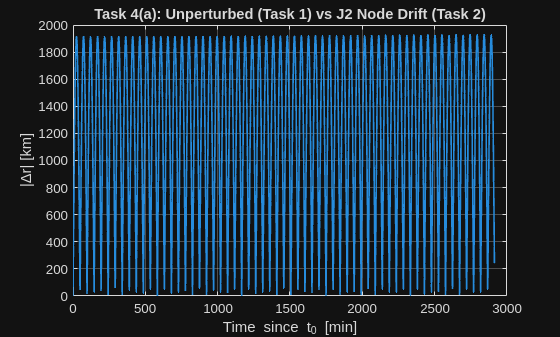

%% === Task 4(a): Unperturbed (Task 1) vs J2 node drift (Task 2) ===
% Inputs expected to exist from your earlier cells:
%   Task 1: t_vec [s], r_eci [km]
%   Task 2: t [s],    R_eci [m]

% 1) Harmonize units (km)
r1_km  = r_eci;           % Task 1 already in km
R2_km  = R_eci/1e3;       % Task 2 to km

% 2) Choose a common time grid (use Task 1's grid) and interpolate Task 2 onto it
t_common = t_vec(:);
R2i_km = [ ...
    interp1(t(:), R2_km(:,1), t_common, 'linear', 'extrap'), ...
    interp1(t(:), R2_km(:,2), t_common, 'linear', 'extrap'), ...
    interp1(t(:), R2_km(:,3), t_common, 'linear', 'extrap') ];

% 3) Differences in ECI/ICRF
dR_12_km = R2i_km - r1_km;             % [km]
dR_12_norm_km = vecnorm(dR_12_km, 2, 2);

% 4) Plots
figure('Name','Task 4(a) |Δr| vs time');
plot((t_common - t_common(1))/60, dR_12_norm_km, 'LineWidth', 1.2);
grid on; xlabel('Time since t_0 [min]'); ylabel('|Δr| [km]');
title('Task 4(a): Unperturbed (Task 1) vs J2 Node Drift (Task 2)');

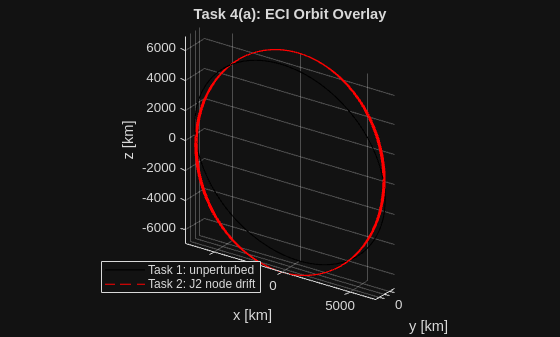


figure('Name','Task 4(a) 3D overlay');
plot3(r1_km(:,1), r1_km(:,2), r1_km(:,3), 'k-', 'LineWidth', 0.8); hold on;
plot3(R2i_km(:,1), R2i_km(:,2), R2i_km(:,3), 'r--', 'LineWidth', 0.8);
grid on; axis equal;
xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');
legend('Task 1: unperturbed','Task 2: J2 node drift','Location','best');
title('Task 4(a): ECI Orbit Overlay');
view(35,25); hold off;

Task 4b)

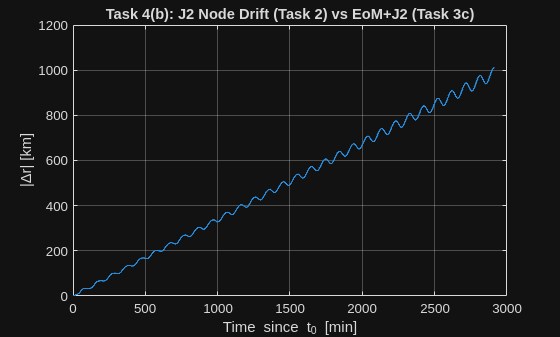

%% === Task 4(b): J2 node drift (Task 2) vs EoM + J2 (Task 3c) ===
% Inputs expected:
%   Task 2: t [s],    R_eci [m]
%   Task 3c: tJ2 [s], R_eci_J2 [m]

% 1) Units to km
R2_km   = R_eci/1e3;         % Task 2
R3J2_km = R_eci_J2/1e3;      % Task 3c

% 2) Interpolate Task 3c onto Task 2's time grid (or vice versa)
t_common = t(:);
R3i_km = [ ...
    interp1(tJ2(:), R3J2_km(:,1), t_common, 'linear', 'extrap'), ...
    interp1(tJ2(:), R3J2_km(:,2), t_common, 'linear', 'extrap'), ...
    interp1(tJ2(:), R3J2_km(:,3), t_common, 'linear', 'extrap') ];

% 3) Differences
dR_23_km = R3i_km - R2_km;           % [km]
dR_23_norm_km = vecnorm(dR_23_km, 2, 2);

% 4) Plots
figure('Name','Task 4(b) |Δr| vs time');
plot((t_common - t_common(1))/60, dR_23_norm_km, 'LineWidth', 1.2);
grid on; xlabel('Time since t_0 [min]'); ylabel('|Δr| [km]');
title('Task 4(b): J2 Node Drift (Task 2) vs EoM+J2 (Task 3c)');

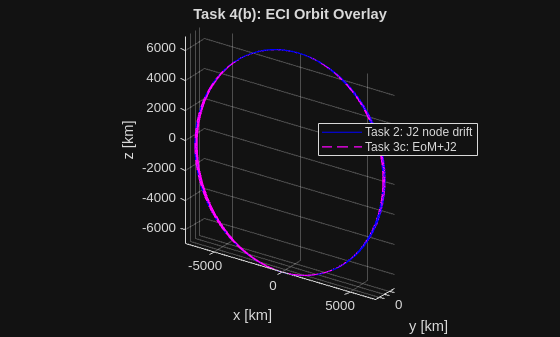


figure('Name','Task 4(b) 3D overlay');
plot3(R2_km(:,1), R2_km(:,2), R2_km(:,3), 'b-',  'LineWidth', 0.8); hold on;
plot3(R3i_km(:,1), R3i_km(:,2), R3i_km(:,3), 'm--', 'LineWidth', 0.8);
grid on; axis equal;
xlabel('x [km]'); ylabel('y [km]'); zlabel('z [km]');
legend('Task 2: J2 node drift','Task 3c: EoM+J2','Location','best');
title('Task 4(b): ECI Orbit Overlay');
view(35,25); hold off;